# Usando Matlab na solução de exercícios

clear all;
clc;
close all;

[https://www.mathworks.com/licensecenter/classroom/COVID-19_Access/](https://www.mathworks.com/licensecenter/classroom/COVID-19_Access/)

## Estabilidade

N  = [1];
D1 = [1 1 1];
D2 = [1 0 1];
D3 = [1 2 1];


Sistema em malha aberta


$$G(s)=\frac{1}{s^2+s+1}
$$


G1 = tf(N,D1)

G1 =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



%%% Pólos

polos = G1.Denominator

polos = 1×1 cell array
    {1×3 double}


polos = cell2mat(polos)

polos =      1     1     1


real(roots(polos))

ans =    -0.5000
   -0.5000


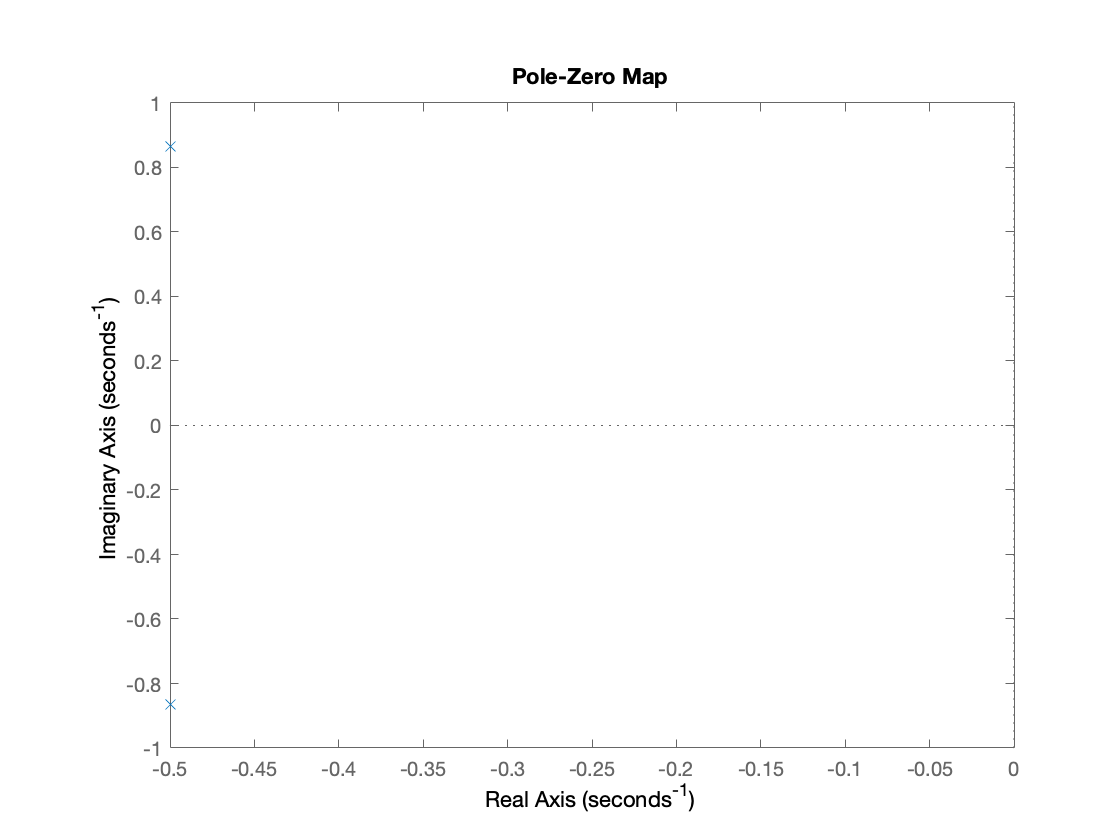

pzmap(G1)

%%% Conclusão: sistema estável em malha aberta

## Erro estacionário

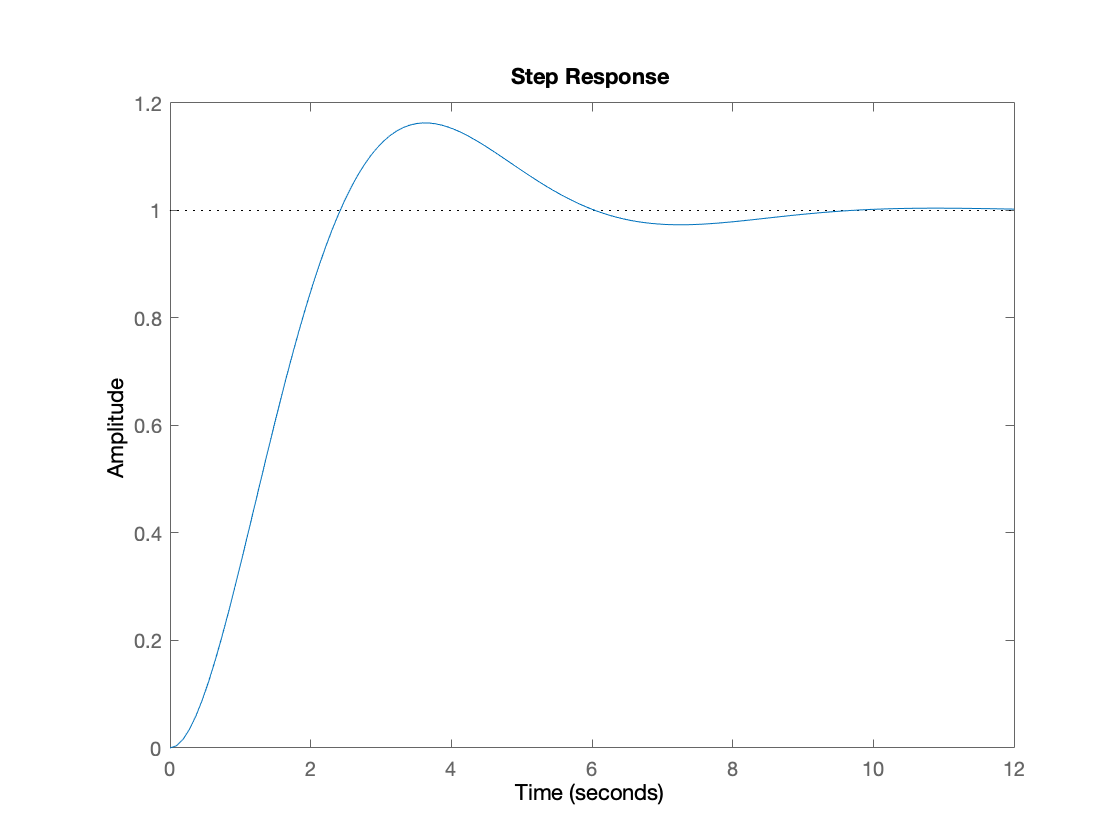

step(G1)

## Malha fechada

Gmf = feedback(G1,1)

Gmf =
 
       1
  -----------
  s^2 + s + 2
 
Continuous-time transfer function.



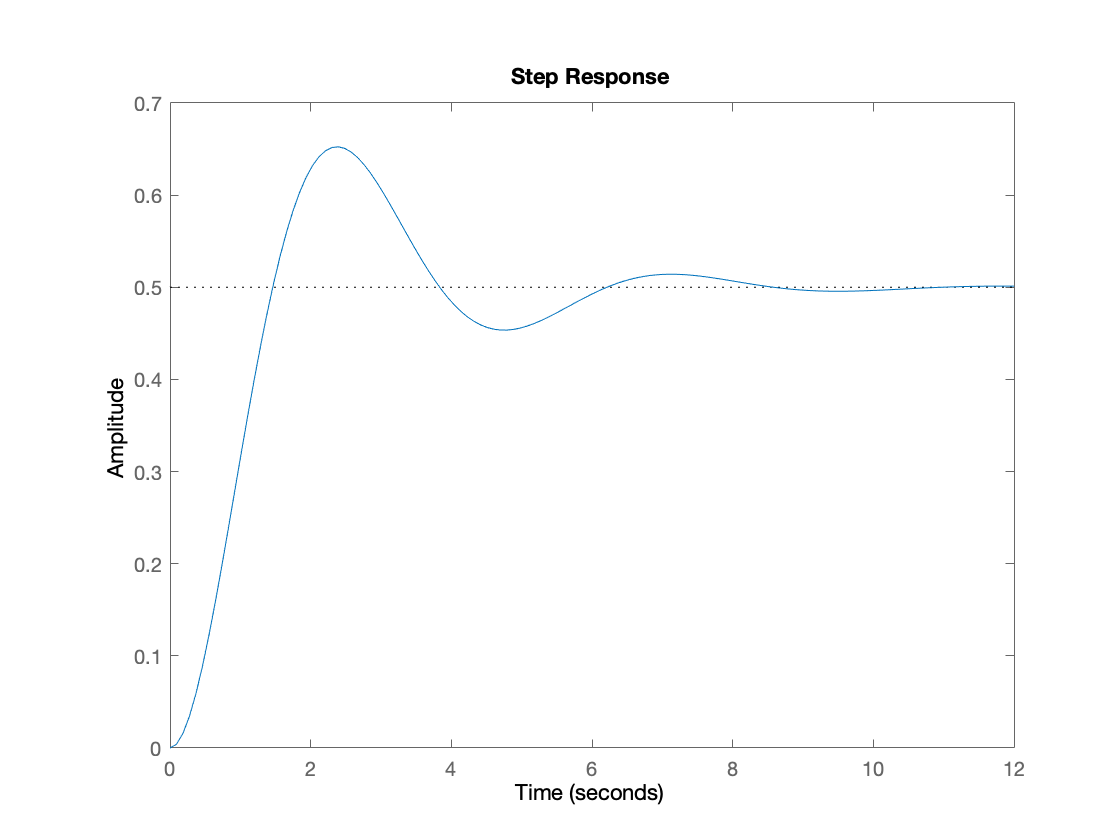

step(Gmf)

## Projeto de controlador


$$G_{ma}(s) = \frac{k}{s^2+s+1}
$$


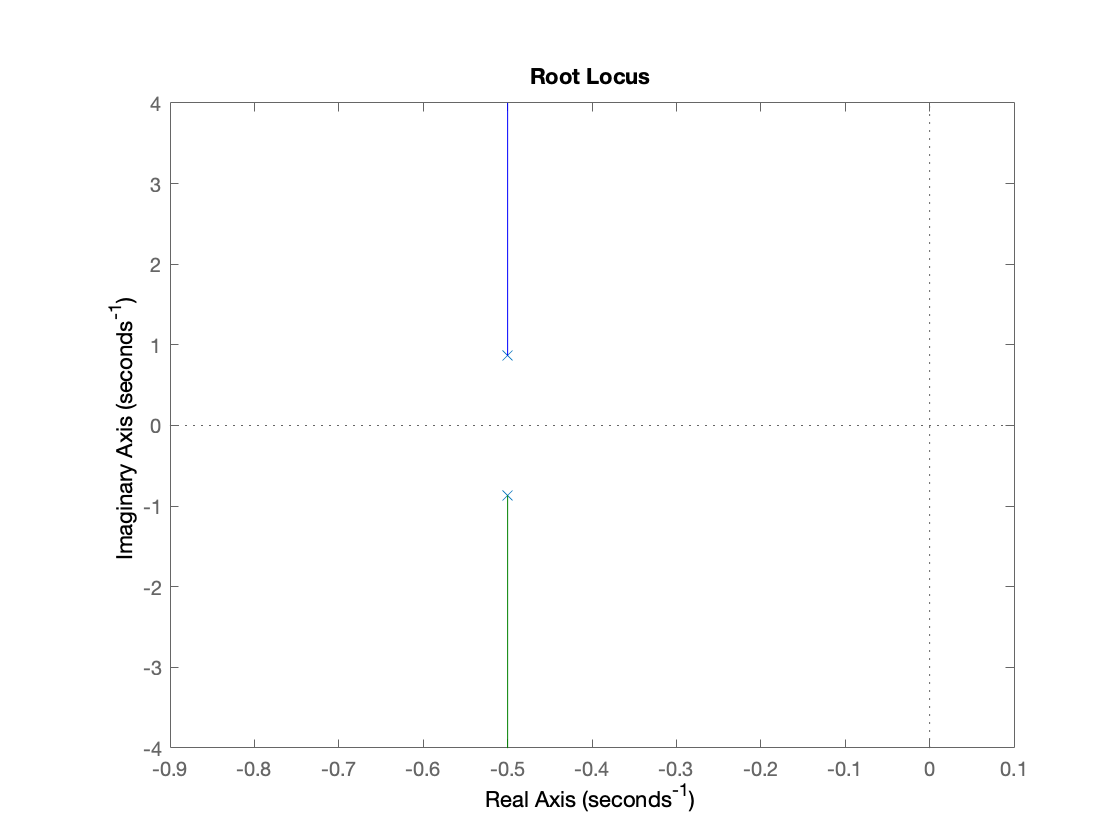

rlocus(G1)

## Fazendo de maneira computacional

Current plot released



k = [0:1:10];

for n = 1:2
    N = k(n);
    D = [1 1 1];
    Gma = tf(N,D);
    Gmf = feedback(Gma,1);
    step(Gmf);
    
    if n==1
        hold;
    end
    Dmf = cell2mat(Gmf.Denominator);
    
    
end